# Metodi iterativi per la risoluzione di sistemi lineari

Vogliamo risolvere un sistema lineare del tipo $Ax=b$ mediante il metodo del gradiente coniugato.

## Introduzione

Scegliamo come matrice dei coefficienti$A \in\mathbb{R}^{N\times N}$ la cosiddetta matrice di Wathen*, *ampiamente utilizzata nei classici problemi di calcolo numerico. La matrice di Wathen è una matrice quadrata di ordine $N$, dipendente dal parametro $n \in \mathbb{N}$, simmetrica e definita positiva. 

MATLAB genera tale matrice in forma sparsa, ovvero non memorizzando gli elementi nulli al suo interno, in modo da minimizzare la quantità di memoria centrale utilizzata.


$$N = 3n^2+4n+1$$
 

n = 500;
N = 3*n^2+4*n+1;
A = distributed(gallery('wathen',n,n));
fprintf("Ordine matrice A: %u \n",N);

Ordine matrice A: 752001 


Scegliamo come vettore-colonna dei termini noti $b \in \mathbb{R}^N$


$$b = \sum_ {A_{i} \in J} A_{i}$$


dove $J = \{A_{1}, A_{2}, ..., A_{N}\}$denota l'insieme delle colonne della matrice $A$.

b = sum(A,2);

È possibile dimostrare che la soluzione del sistema $x_\text{exact} \in \mathbb{R}^N$ sia pari a


$$x_\text{exact} = [1, 1, ...,1]^T$$


xExact = ones(N,1,'distributed');

## Metodo del gradiente coniugato con parametri di default

Come primo tentativo, risolviamo il sistema con il metodo del gradiente coniugato, un metodo per la risoluzione di sistemi lineari che ad ogni passo genera una serie di soluzioni approssimate per $x_\text{exact}$.

La funzione MATLAB [`pcg`](https://it.mathworks.com/help/matlab/ref/pcg.html) fornisce un'implementazione parallela del metodo del gradiente coniugato, che restituisce in output una lista di parametri tra cui figurano

- `xCG:` la soluzione approssimata per il sistema $Ax=b$;

- `flagCG`: un flag booleano indicante se il metodo del gradiente coniugato converge, a meno della tolleranza desiderata;

- `resvecCG`: un vettore in cui ciascun elemento corrisponde al residuo normalizzato al termine di ogni iterazione, calcolato come  $$ \frac{|| b-Ax ||}{ || b ||}$$.  Si tratta di una metrica indicante l'accuratezza della soluzione calcolata tra un'iterazione e la successiva.

Inoltre, il criterio di arresto del metodo dipende da due ulteriori parametri: `maxIt`, il numero massimo di iterazioni, e `tolerance` rappresentante l'accuratezza della soluzione trovata al termine dell'algoritmo. Nel caso in esame,

`tolerance` = $10^{-6}$

`maxIt` = $\min \{20;N\}$ = $20$

[xCG_1,flagCG_1,relresCG_1,iterCG_1,resvecCG_1] = pcg(A,b);

Procediamo con il calcolo dell'errore assoluto `errCG` tra le componenti corrispondenti di $x_\text{exact}$ ed `xCG.`

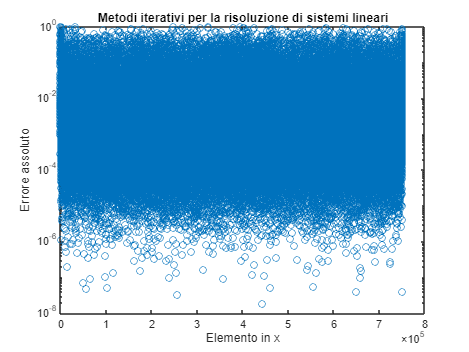

errCG_1 = abs(xExact - xCG_1);

figure(1)
semilogy(errCG_1,'o');
title('Metodi iterativi per la risoluzione di sistemi lineari');
ylabel('Errore assoluto');
xlabel('Elemento in x');

Notiamo che l'errore assoluto è elevato; infatti, il metodo del gradiente coniugato non converge nel caso in esame a partire dal numero di iterazioni a disposizione. 

flagCG_1

flagCG_1 = 1

## Metodo del gradiente coniugato con parametri personalizzati

Come secondo tentativo, modifichiamo i valori relativi ai parametri `maxIt` e `tolerance`, con l'obiettivo di aumentare la probabilità che l'algoritmo converga. In particolare, impostiamo `tolerance` pari a $10^{-12}$ e forziamo il numero di iterazioni pari a $N$.

tolerance = 1e-12;
maxit = N;      

tCG = tic;
[xCG_2,flagCG_2,relresCG_2,iterCG_2,resvecCG_2] = pcg(A,b,tolerance,maxit);
tCG = toc(tCG);

In questa configurazione personalizzata, il metodo del gradiente coniugato converge.

flagCG_2

flagCG_2 = 0

Complessivamente, l'errore assoluto risulta diminuito rispetto al tentativo precedente.

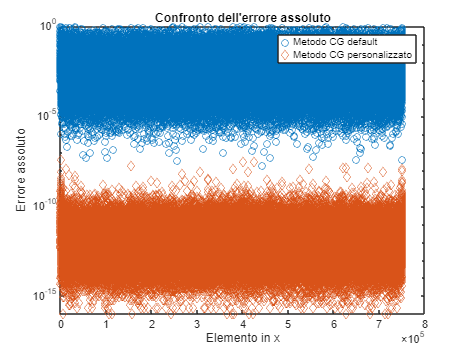

errCG_2 = abs(xExact - xCG_2);

figure(2)
semilogy(errCG_1,'o');
hold on
semilogy(errCG_2,'diamond');
title("Confronto dell'errore assoluto");
ylabel('Errore assoluto');
xlabel('Elemento in x');
legend('Metodo CG default','Metodo CG personalizzato');
hold off

Procediamo con il calcolo dei residui relativi alla prima iterazione per individuare il motivo per cui il metodo del gradiente coniugato è risultato non convergente al primo tentativo.

relresvecCG = resvecCG_2./resvecCG_2(1);

Dal grafico in figura, notiamo come sia impossibile raggiungere una soluzione sufficientemente approssimata per il sistema in questione con il numero di iterazioni di default.

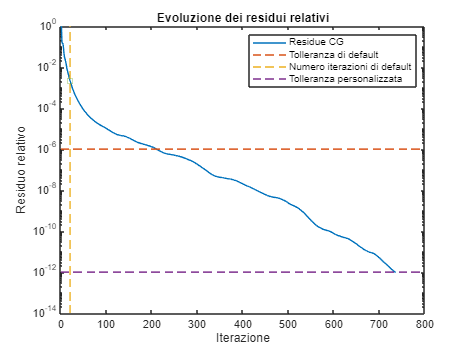

px = 20;
py = relresvecCG(px);

figure(3)
f=semilogy(relresvecCG);
hold on
semilogy(f.Parent.XLim,[1e-6 1e-6],'--')
semilogy([20 20], f.Parent.YLim,'--')
semilogy(f.Parent.XLim,[1e-12 1e-12],'--')
plot(px,py, '-s')
title('Evoluzione dei residui relativi');
ylabel('Residuo relativo');
xlabel('Iterazione');
legend('Residue CG','Tolleranza di default','Numero iterazioni di default','Tolleranza personalizzata')
hold of